# Decomposition of HD-sEMG

Prof. Carina Marconi Germer

UNIVERSIDADE ESTADUAL DE CAMPINAS

#### Mathmatical contextualization

In electromyography, the observations (i.e., the signals recorded) comprise the summation of the action potential trains of all motor units recruited. Each motor unit has a specific action potential shape per channel as it depends on its anatomical characteristics (e.g., size, type of innervated fibers and deepness), the volume conductor characteristics (e.g., tissues conductivities and thickness) and the recording system (e.g., electrode size, inter-electrode distance and recording mode). 

(Figura PA nos canais)

The problem is then usually modeled as instantaneous convolutive mixture, as it consists of the convolutional combination of action potential waveform and the discharge times. The model is said instantaneous because we assume the source signals arrive at the sensors at the same time. In this model, the sources are the discharge trains of motor units, and the mixing matrix comprises the filter from the action potential shapes at each electrode. We also assume the waveform is invariant in the time, which is true for isometric contractions. 

Assuming N active neurons are recorded by M electrodes, the signal on each channel can be described as:

                             $x_m {\left(t\right)}=\ \sum_{l=0}^{L-1} \sum_{n=1}^N a_{nm} {\left(l\right)}s_n {\left(t-l\right)}+\eta_m {\left(t\right)},\ \ \ \ \ m=1,\ldots,M;\ \ t=0,\ldots,D_R$              (1)

Where $x_m$ is the observation in the *m**th* channel at the time instant *t* (in the discrete time), $D_R$ is the duration of the recording (in samples), $a_{nm} {\left(l\right)}$ is the action potential waveform of the *n**th *motor unit in the* m**th* channel, *L *is the length of the action potential waveform, $s_n$ is the discharge train of the *n**th *neuron modelled by a series of Dirac Delta function ($s_n {\left(t\right)}=\sum_k \delta \left(t-T_n {\left(k\right)}\right)$ , where $T_n$ are the discharge instants), and $\eta_m$ is the noise at channel *m. *Due to the refractory period, we can assume no overlapping of action potentials in the same motor unit, thus $T_n {\left(k+1\right)}-T_n {\left(k\right)}>L$  for $\forall k\in \mathbb{N}$. 

In the vector-matrix notation, Equation (1) becomes

           $\mathit{\mathbf{x}}{\left(t\right)}=\ \sum_{l=0}^{L-1} \mathit{\mathbf{A}}{\left(l\right)}\mathit{\mathbf{s}}{\left(t-l\right)}+\eta \left(t\right)$              (2)

Equation (2) is a finite impulse response (FIR) model, where $\mathit{\mathbf{x}}\left(t\right)={{\left[x_1 \left(t\right),x_2 \left(t\right),\ldots,\ x_M \left(t\right)\right]}}^T$  is the vector of observations,  $\mathit{\mathbf{A}}{\left(l\right)}={\left[{\mathit{\mathbf{a}}}_1 {\left(l\right)},\ldots,{\mathit{\mathbf{a}}}_{\mathit{\mathbf{N}}} {\left(l\right)}\right]}$ is the action potential filter of order L and size *M x N, *and $\mathit{\mathbf{s}}{\left(t\right)}={{\left[s_1 {\left(t\right)},\ldots,s_N {\left(t\right)}\right]}}^T$ is the vector of sources at time instant *t*. Superscript *T* denotes transposition of a vector or a matrix. 

The simplest approach to separate a convolutive instantaneous mixture is to represent it as a standard linear model by its compact form. First, the convolutive model is rewritten in its matrix form

 $\mathit{\mathbf{x}}{\left(t\right)}=\ \underline{\mathit{\mathbf{A}}\mathit{\mathbf{s}}} {\left(t\right)}+\eta \left(t\right)\in {\mathbb{R}}^{M\mathrm{x}1}$             (3)

Where $\underline{\mathit{\mathbf{A}}} ={\left[\mathit{\mathbf{A}}{\left(0\right)},\mathit{\mathbf{A}}{\left(1\right)},\ldots,\mathit{\mathbf{A}}{\left(L-1\right)}\right]}\in {\mathbb{R}}^{M\mathrm{x}NL}$ , and $\underline{\mathit{\mathbf{s}}} \left(\mathit{\mathbf{t}}\right)={{\left[{\mathit{\mathbf{s}}}^T {\left(t\right)},{\mathit{\mathbf{s}}}^T {\left(t-1\right)},\ldots,{\mathit{\mathbf{s}}}^T {\left(t-L+1\right)}\right]}}^T \in {\mathbb{R}}^{NL\mathrm{x}1}$ contains the latest L samples of the sources. 

By using a sliding window of length K+1, here after referred to as the extension factor, it yields to a block-based model

                   $\overset{~}{\mathit{\mathbf{x}}} {\left(t\right)}=\overset{~}{\mathit{\mathbf{A}}} \overset{~}{\mathit{\mathbf{s}}} {\left(t\right)}+\overset{~}{\eta} \left(t\right)\in {\mathbb{R}}^{M{\left(K+1\right)}\mathrm{x}1}$     (4)

Where, $\overset{~}{\mathit{\mathbf{x}}} {\left(t\right)}={{\left[{\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} {\left(t\right)},{\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} {\left(t-1\right)},\ldots,{\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} {\left(t-K\right)}\right]}}^T$, is the extended vector of observations containing the original signals and K delayed versions, and

$\overset{~}{\mathit{\mathbf{A}}} ={\left[\begin{array}{ccccccc}
\mathit{\mathbf{A}}\left(0\right) & \mathit{\mathbf{A}}\left(1\right) & \ldots & \mathit{\mathbf{A}}\left(L-1\right) & 0 & \ldots & 0\\
0 & \mathit{\mathbf{A}}\left(0\right) & \ldots & \mathit{\mathbf{A}}\left(L-2\right) & \mathit{\mathbf{A}}\left(L-1\right) & \ldots & 0\\
\vdots  & \ddots  & \ddots  & \ddots  & \ddots  & \ddots  & \vdots \\
0 & \ldots & 0 & \mathit{\mathbf{A}}\left(0\right) & \ldots & \mathit{\mathbf{A}}\left(L-2\right) & \mathit{\mathbf{A}}\left(L-1\right)
\end{array}\right]}\in {\mathbb{R}}^{M{\left(K+1\right)}\mathrm{x}\mathrm{N}\left(\mathrm{L}+\mathrm{K}\right)}$ , 

 $\overset{~}{\mathit{\mathbf{s}}} {\left(t\right)}={{\left[{\mathit{\mathbf{s}}}^T {\left(t\right)},{\mathit{\mathbf{s}}}^T {\left(t-1\right)},\ldots,{\mathit{\mathbf{s}}}^T \left(t-L-K+1\right)\right]}}^T \in {\mathbb{R}}^{N{\left(L+K\right)}\mathrm{x}1}$, and

  
$$\overset{~}{\eta} {\left(t\right)}={{\left[\eta^T {\left(t\right)},\eta^T {\left(t-1\right)},\ldots,\eta^T \left(t-K\right)\right]}}^T \in {\mathbb{R}}^{N{\left(L+K\right)}\mathrm{x}1}$$


The mixing matrix $\overset{~}{\mathit{\mathbf{A}}}$ is a generalized Sylvester block Toeplitz matrix, having  $K+1$ vertical and $L+K$  horizontal  $M\mathrm{x}N$ blocks, and is full column rank. 

Equation 4 models the mixture system and the demixing system is fiven by Equation 5

                                  $\hat{s} \left(t\right)=\overset{~}{\mathit{\mathbf{D}}} \overset{~}{\mathit{\mathbf{x}}} {\left(t\right)}$           (5)

 Where $\overset{~}{\mathit{\mathbf{D}}} \mathit{\mathbf{\ }}\in {\mathbb{R}}^{N{\left(L+K\right)}\mathrm{x}M{\left(K+1\right)}}$ is the matrix of coefficients of the separating system filters, also called matrix of weights, and $\widehat{s} \left(t\right)$  is the estimated source vector. The demixing problem builds on the fundamental assumption of statistical independence or sparseness (non-Gaussianity) of the sources. The model also assumes that the source signal vector are zero-mean stationary real signals and is independent of the noise vector. To make the zero-mean assumption hold we center the observation matrix by subtracting their sample mean. Moreover, the extension factor (K+1) should be large enough to assure   to yield to an overdetermined multiple-input multiple-output demixing model. 

Once the convolutive mixture model (Equation 1) is approximated to an instantaneous linear mixture model (Equation 5), we can proceed to the separation problem by standard linear independent component analysis. The approach chosen was fastICA.

## Decomposition of HD-sEMG

In the following example, you will be ...

...

### Load Data

 
close all; clear, clc

Example = "Steady_5MVC";

% load data
switch Example
    case 'Steady_5MVC'
        load EMG_AV_5_00_2.mat;
    case 'Trapezoidal_15MVC'
        load C15_Ne_VF_S_01_EMG.mat;
end

fprintf('done!')

done!

### Pre-process the Observations

#### Unselect "bad-channels"

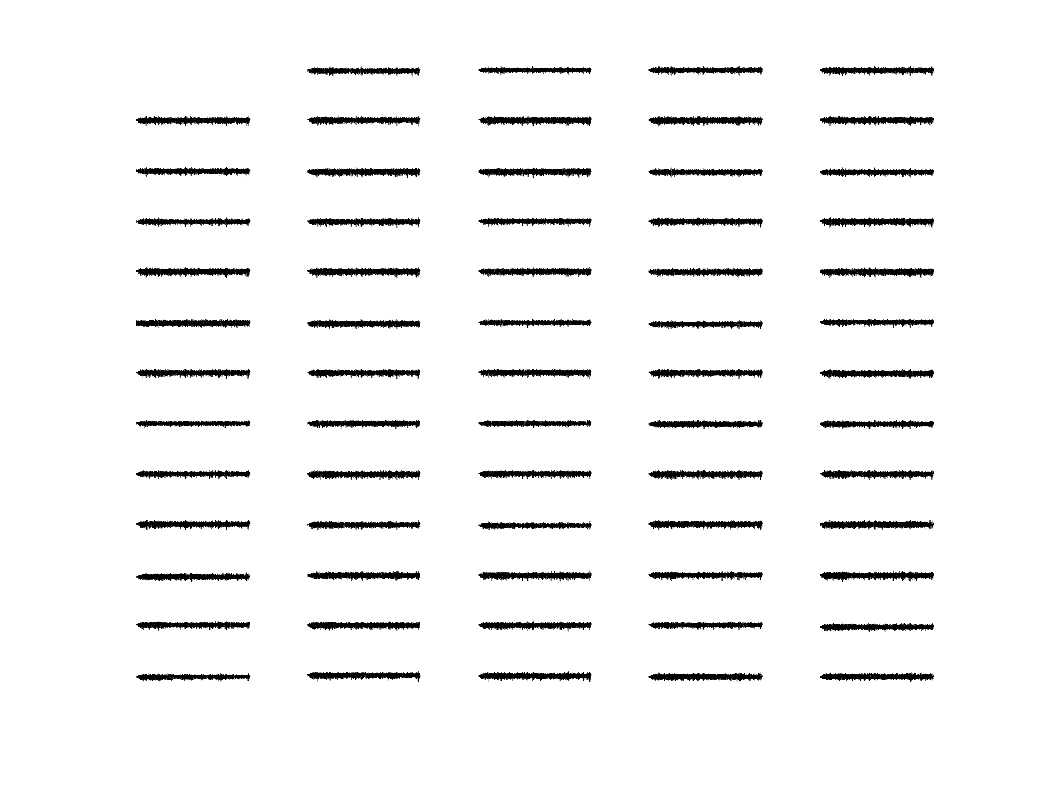

figure()
t=(1:length(SIG{2}))/fsamp;
for ch=1:numel(SIG)
    subplot(size(SIG,1),size(SIG,2),ch)
    if ~isempty(SIG{ch})
        plot(t,SIG{ch},'k');
    end
    set(gca,'Visible','off')
    title(sprintf('Ch%d',ch))
end

- Whiten



% Extend Observations
eYT = extension(Data,extFact); 
eYT = eYT - repmat(mean(eYT,2),1,size(eYT,2));

% whitening using SVD
[U,S,V] = svd(eYT*eYT'/length(eYT));    % SVD correlation matrix
FACT = prctile(diag(S),25);         % remove eigenvectors
SI = 1./sqrt(diag(S) + FACT);           % inverse eigenvalues
WM = U * diag(SI) * V';                 % whitening matrix

eYW = WM * eYT;                         % whitened extended signals


## References